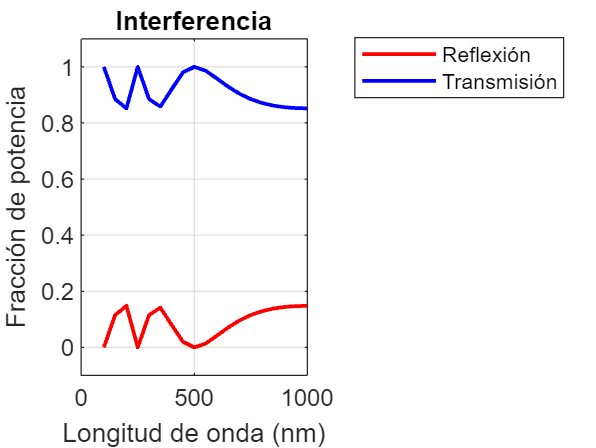

lambdas = 100e-9:50e-9:100e-8; % rango de longitudes de onda
R = zeros(size(lambdas));
T = zeros(size(lambdas));

for k = 1:length(lambdas)
    [Hr,Ht,Pi,Pr,Pt] = inter(1,0,[1,1.5,1],[500e-9,500e-9],lambdas(k),false);
    R(k) = Pr/Pi;
    T(k) = Pt/Pi;
end

figure;
plot(lambdas*1e9,R,'r',lambdas*1e9,T,'b','LineWidth',1.5);
xlabel('Longitud de onda (nm)');
ylabel('Fracción de potencia');
legend('Reflexión','Transmisión','Location','northeastoutside'); % fuera del grid
title('Interferencia');
grid on;
ylim([-0.1 1.1]);